x = [1 2 3 4 5];
y = [5.5 43.1 128 290.7 498.4];


p = polyfit(x, y, 3);  % Fit a third-degree polynomial


y_fit = polyval(p, x)  % Evaluate the polynomial at the same points as x

y_fit =     6.4043   39.4829  133.4257  287.0829  499.3043


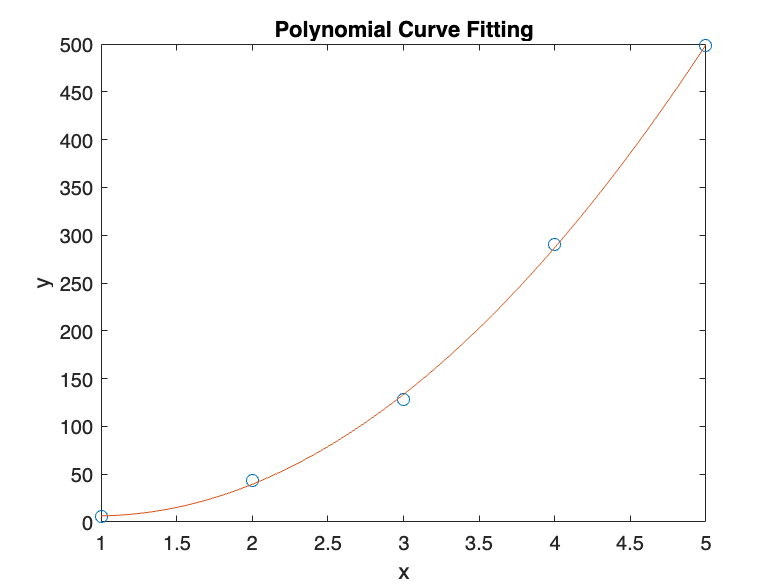


x_new = linspace(1, 5, 100);  % Create a finer grid of points
y_new = polyval(p, x_new);  % Evaluate the polynomial at the new points


plot(x, y, 'o', x_new, y_new);
xlabel('x');
ylabel('y');
title('Polynomial Curve Fitting');

n = 8;  % Size of the matrix
a = randi(n, n, 1);  % Lower diagonal
b = randi(n, n, 1);    % Main diagonal
c = randi(n, n, 1);  % Upper diagonal
T_sparse = spdiags([a b c], -1:1, n, n);  % Construct tridiagonal matrix
T = full(T_sparse);

A = bandmatrix_1067400(T)

A =      0     5     8     1     5     5     1     8
     6     7     4     4     8     5     7     3
     7     1     7     7     3     4     5     0


x= randi(3,n,1)

x =      3
     2
     3
     1
     2
     1
     2
     3



B = T*x

B =     28
    59
    15
    35
    28
    13
    42
    19


D = diag(A(2,:));
L = diag(A(3,1:end-1),-1)*-1;
U = diag(A(1,2:end),1)*-1;

A=debandmatrix_1067400(A);

n = size(A, 2);


for k = 1:(log2(n))
    D = diag(diag(A));
    L = tril(A,-1);
    U = triu(A,1);
    D_inv = inv(D);

    A = A*D_inv*(D-L-U)
    B = A*D_inv* B;
end

A =     1.0000   -0.0000   -5.7143         0         0         0         0         0
   -0.0000   -0.8333         0   -2.0000         0         0         0         0
   -1.0000         0    1.1071         0   -1.2500         0         0         0
         0   -1.7500         0   -2.1250         0   -3.1250         0         0
         0         0  -12.2500         0   -3.7500         0   -1.0000         0
         0         0         0   -2.6250         0    2.5536   -0.0000   -1.1429
         0         0         0         0   -2.4000         0   -7.1333   -0.0000
         0         0         0         0         0   -2.8571   -0.0000   -2.7143


A =    -4.1613    0.0000    0.0000    0.0000   -6.4516         0         0         0
         0    0.8137   -0.0000    0.0000         0    2.9412         0         0
         0   -0.0000   -0.5238         0    0.0000         0    0.3333         0
    0.0000   -0.0000         0   -1.1374         0    0.0000   -0.0000   -1.3986
  -11.0645         0         0         0  -17.2442         0   -0.0000    0.0000
         0    2.1618         0         0    0.0000    7.6169    0.0000    0.0000
         0         0    7.8400         0         0    0.0000   -6.4933    0.0000
         0         0         0   -2.9371    0.0000    0.0000   -0.0000   -3.9930


A =    -0.0217   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.0000   -0.0210    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
   -0.0000         0   -0.1213    0.0000   -0.0000    0.0000    0.0000    0.0000
         0   -0.0000   -0.0000   -0.1087   -0.0000    0.0000    0.0000   -0.0000
         0   -0.0000   -0.0000   -0.0000   -0.0899    0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.1967    0.0000   -0.0000
         0   -0.0000         0   -0.0000    0.0000    0.0000   -1.5042   -0.0000
   -0.0000    0.0000   -0.0000         0         0   -0.0000    0.0000   -0.3815


    x = B./diag(A)

x =    10.1373
   -3.9302
   -8.9842
   30.6677
    6.5949
   -0.8771
   12.5102
   23.4242
